filenamePredictors = fullfile("C:\Users\crist\Downloads\CMAPSSData","train_FD001.txt");
[XTrain1,YTrain1] = processTurboFanDataTrain(filenamePredictors);

m = min([XTrain1{:}],[],2);
M = max([XTrain1{:}],[],2);
idxConstant = M == m;

for i = 1:numel(XTrain1)
    XTrain1{i}(idxConstant,:) = [];
end
numFeatures = size(XTrain1{1},1)
mu = mean([XTrain1{:}],2);
sig = std([XTrain1{:}],0,2);

for i = 1:numel(XTrain1)
    XTrain1{i} = (XTrain1{i} - mu) ./ sig;
end

thr = 150;
for i = 1:numel(YTrain1)
    YTrain1{i}(YTrain1{i} > thr) = thr;
end


for i=1:numel(XTrain1)
    sequence = XTrain1{i};
    sequenceLengths(i) = size(sequence,2);
end

[sequenceLengths,idx] = sort(sequenceLengths,'descend');
XTrain1 = XTrain1(idx);
YTrain1 = YTrain1(idx);

class(XTrain1)
class(YTrain1)
class(YTrain1{1})
class(XTrain1{1})
%class(YTrain1{1}{1})
%class(XTrain1{1}{1})
%class(YTrain1{1}{1}{1})
%class(XTrain1{1}{1}{1})





miniBatchSize = 20;


numResponses = size(YTrain1{1},1);
numHiddenUnits = 200;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(50)
    dropoutLayer(0.5)
    fullyConnectedLayer(numResponses)
    regressionLayer];

maxEpochs = 60;
miniBatchSize = 20;

XTrain1

YTrain1




T = readtable('C:\Users\crist\Documents\AES tests\tstnew1_output_short4.csv');


XTrain = cell(length(T.TEXT), 1)
YTrain = cell(length(T.TEXT), 1)
for j=1:length(XTrain)
    aa = double(T.TEXT{j})
    w = zeros(1, length(T.TEXT{j}))
    z = zeros(1, length(T.TEXT{j}))
    for i=1:length(T.TEXT{j})
        substr = extractBetween(T.ENCRYPTED{j},i*2-1,i*2)
        z(1,i) = hex2dec(substr{1})
        w(1,i) = aa(1,i)
    end
    XTrain{j} = w
    YTrain{j} = z 
end





numFeatures = size(YTrain{1},1)

numFeatures = 1

numResponses = size(XTrain{1},1);
numHiddenUnits = 200;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(128)
    dropoutLayer(0.5)
    fullyConnectedLayer(256)
    dropoutLayer(0.5)
    fullyConnectedLayer(256)
    dropoutLayer(0.5)
    fullyConnectedLayer(128)
    dropoutLayer(0.5)
    fullyConnectedLayer(numResponses)
    regressionLayer];

maxEpochs = 60;
miniBatchSize = 20;

options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',0.01, ...
    'GradientThreshold',1, ...
    'Shuffle','never', ...
    'Plots','training-progress',...
    'Verbose',0);

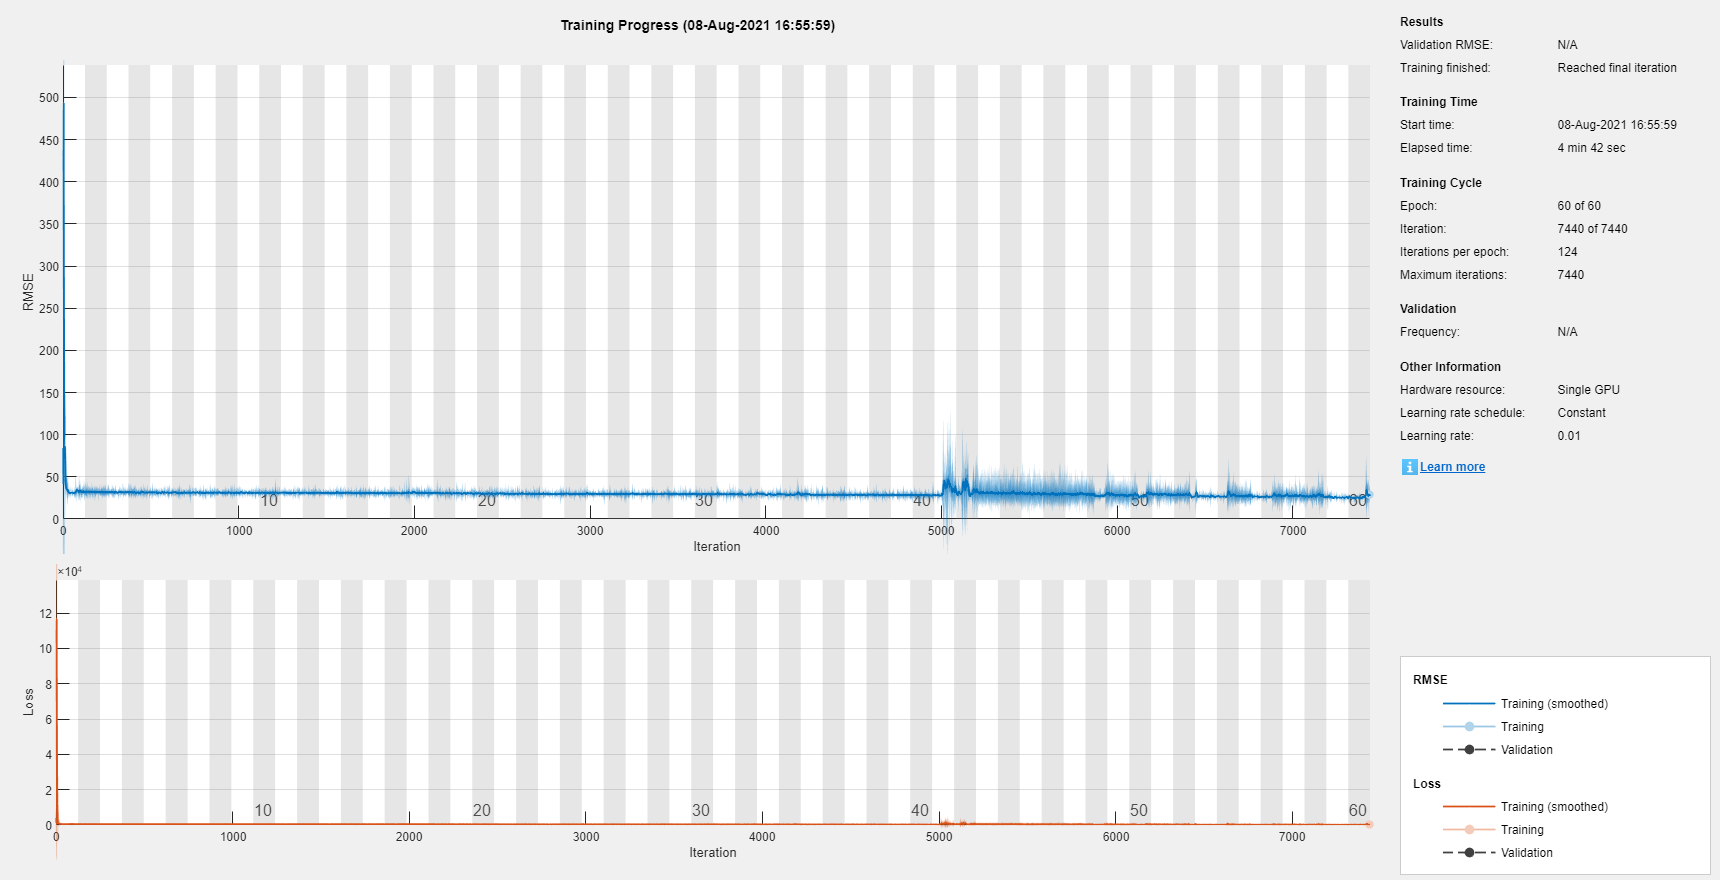



net = trainNetwork(YTrain,XTrain,layers,options);


YPred = predict(net,YTrain,'MiniBatchSize',1);


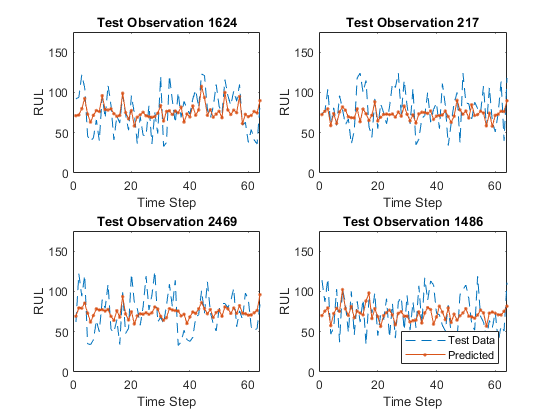

thr = 150;
idx = randperm(numel(YPred),4);
figure
for i = 1:numel(idx)
    subplot(2,2,i)
    
    plot(XTrain{idx(i)},'--')
    hold on
    plot(YPred{idx(i)},'.-')
    hold off
    
    ylim([0 thr + 25])
    title("Test Observation " + idx(i))
    xlabel("Time Step")
    ylabel("RUL")
end
legend(["Test Data" "Predicted"],'Location','southeast')



for i = 1:numel(XTrain)
    YTestLast(i) = XTrain{i}(end);
    YPredLast(i) = YPred{i}(end);
end
figure
rmse = sqrt(mean((YPredLast - YTestLast).^2))

rmse = single
21.7726

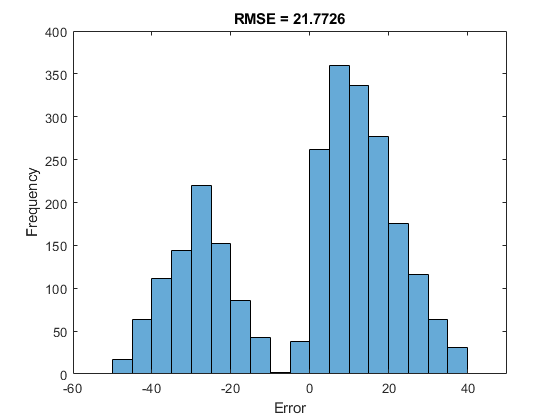

histogram(YPredLast - YTestLast)
title("RMSE = " + rmse)
ylabel("Frequency")
xlabel("Error")

%NO!!!!!!!

layers2 = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];
options2 = trainingOptions('adam', ...
    'MaxEpochs',60, ...
    'GradientThreshold',2, ...
    'Verbose',0, ...
    'Plots','training-progress');

net = trainNetwork(YTrain,XTrain,layers2,options2);

Error using trainNetwork (line 184)
Invalid training data. Responses must be a cell array of categorical response sequences.